# **Comparing Iterative Methods for Solving Nonlinear Systems**

This live script demonstrates four iterative methods for solving nonlinear systems, including Newton's method, Broyden's method, Steepest Descent, and Gauss-Newton method.

All four of the methods are applied to the system in the function `fun.m`.

### Newton's Method

p = [0.5,0,-0.52359877];
p = p(:);
x0 = [0.1,0.1,-0.1];
Newton_errors = [];

newton_iters = newton(x0,10^-9,20);

k      ||f(x_k)||  
0      8.842957e+00      
1      3.459245e-01      
2      2.589220e-02      
3      2.012689e-04      
4      1.254881e-08      
5      1.803899e-15      


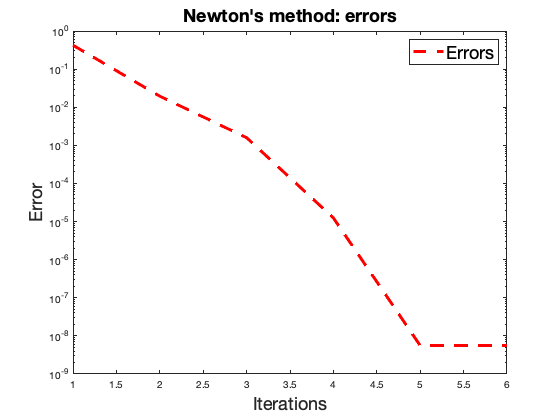

k1 = length(newton_iters);

for i = 1:k1
   Newton_errors(i) = norm(newton_iters(:,i) - p,'inf'); 
end

semilogy(1:k1,Newton_errors,'r--','Linewidth',3)
ylabel('Error','FontSize',18)
xlabel('Iterations','FontSize',18)
title("Newton's method: errors",'FontSize',18)
legend('Errors', 'FontSize',18)

### Broyden's Method

p = [0.5,0,-0.52359877];
p = p(:);
x0 = [0.1,0.1,-0.1];
Broyden_errors = [];

Broyden_iters = Broyden(x0,10^-9,20);

         0.499869685848043
        0.0194680768263487
        -0.521480478156492

         0.499986368569457
       0.00873764107679178
        -0.523174807659963

         0.500006586067859
      0.000873569278268631
        -0.523571953689866

         0.500000331013985
      3.98187042239235e-05
        -0.523597676913232

         0.500000001589781
      1.98308473592001e-07
        -0.523598769885714

         0.500000000000344
     -7.24421325202543e-12
        -0.523598775599473

                       0.5
      2.00234871320864e-13
         -0.52359877559829



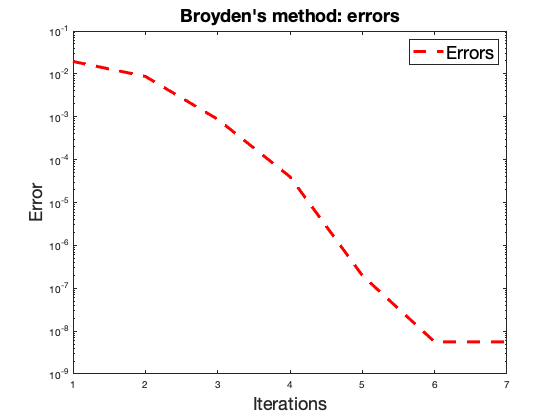

k2 = length(Broyden_iters);

for i = 1:k2
   Broyden_errors(i) = norm(Broyden_iters(:,i) - p,'inf'); 
end

semilogy(1:k2,Broyden_errors,'r--','Linewidth',3)
ylabel('Error','FontSize',18)
xlabel('Iterations','FontSize',18)
title("Broyden's method: errors",'FontSize',18)
legend('Errors', 'FontSize',18)

### Newton's Method vs. Broyden's Method: Time

p = [0.5,0,-0.52359877];
p = p(:);
x0 = [0.1,0.1,-0.1];
newtont_iters = [];
Broydent_iters = [];

newtont_iters = newtont(x0,10^-19,100);

k      ||f(x_k)||  
0      8.842957e+00      
1      3.459245e-01      
2      2.589220e-02      
3      2.012689e-04      
4      1.254881e-08      
5      1.803899e-15      
6      1.790181e-15      
7      1.776357e-15      
8      1.776357e-15      
9      1.776357e-15      
10      1.776357e-15      
11      1.776357e-15      
12      1.776357e-15      
13      1.776357e-15      
14      1.776357e-15      
15      1.776357e-15      
16      1.776357e-15      
17      1.776357e-15      
18      1.776357e-15      
19      1.776357e-15      
20      1.776357e-15      
21      1.776357e-15      
22      1.776357e-15      
23      1.776357e-15      
24      1.776357e-15      
25      1.776357e-15      
26      1.776357e-15      
27      1.776357e-15      
28      1.776357e-15      
29      1.776357e-15      
30      1.776357e-15      
31      1.776357e-15      
32      1.776357e-15      
33      1.776357e-15      
34      1.776357e-15      
35      1.776357e-15      
36      1.776357e-

Broydent_iters = Broydent(x0,10^-19,100);

         0.499869685848043
        0.0194680768263487
        -0.521480478156492

         0.499986368569457
       0.00873764107679178
        -0.523174807659963

         0.500006586067859
      0.000873569278268631
        -0.523571953689866

         0.500000331013985
      3.98187042239235e-05
        -0.523597676913232

         0.500000001589781
      1.98308473592001e-07
        -0.523598769885714

         0.500000000000344
     -7.24421325202543e-12
        -0.523598775599473

                       0.5
      2.00234871320864e-13
         -0.52359877559829

                       0.5
      4.54513513312427e-15
        -0.523598775598299

                       0.5
     -3.66958131398628e-18
        -0.523598775598299

                       0.5
      1.60201447151849e-17
        -0.523598775598299

                       0.5
       -3.672483920509e-19
        -0.523598775598299

                       0.5
     -4.75213522589013e-17
        -0.523598775598299

                

newtonx_iters = newton(x0,10^-19,100);

k      ||f(x_k)||  
0      8.842957e+00      
1      3.459245e-01      
2      2.589220e-02      
3      2.012689e-04      
4      1.254881e-08      
5      1.803899e-15      
6      1.790181e-15      
7      1.776357e-15      
8      1.776357e-15      
9      1.776357e-15      
10      1.776357e-15      
11      1.776357e-15      
12      1.776357e-15      
13      1.776357e-15      
14      1.776357e-15      
15      1.776357e-15      
16      1.776357e-15      
17      1.776357e-15      
18      1.776357e-15      
19      1.776357e-15      
20      1.776357e-15      
21      1.776357e-15      
22      1.776357e-15      
23      1.776357e-15      
24      1.776357e-15      
25      1.776357e-15      
26      1.776357e-15      
27      1.776357e-15      
28      1.776357e-15      
29      1.776357e-15      
30      1.776357e-15      
31      1.776357e-15      
32      1.776357e-15      
33      1.776357e-15      
34      1.776357e-15      
35      1.776357e-15      
36      1.776357e-

Broydenx_iters = Broyden(x0,10^-19,100);

         0.499869685848043
        0.0194680768263487
        -0.521480478156492

         0.499986368569457
       0.00873764107679178
        -0.523174807659963

         0.500006586067859
      0.000873569278268631
        -0.523571953689866

         0.500000331013985
      3.98187042239235e-05
        -0.523597676913232

         0.500000001589781
      1.98308473592001e-07
        -0.523598769885714

         0.500000000000344
     -7.24421325202543e-12
        -0.523598775599473

                       0.5
      2.00234871320864e-13
         -0.52359877559829

                       0.5
      4.54513513312427e-15
        -0.523598775598299

                       0.5
     -3.66958131398628e-18
        -0.523598775598299

                       0.5
      1.60201447151849e-17
        -0.523598775598299

                       0.5
       -3.672483920509e-19
        -0.523598775598299

                       0.5
     -4.75213522589013e-17
        -0.523598775598299

                

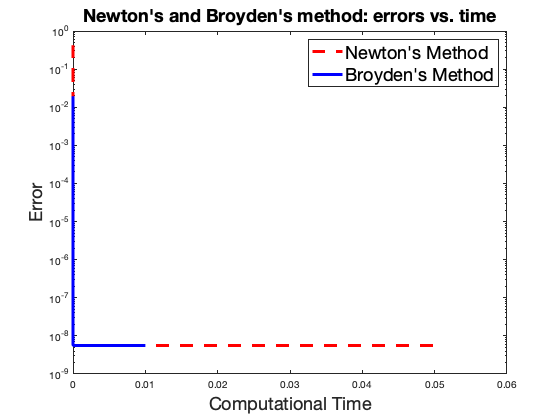

k1t = length(newtont_iters);
k2t = length(Broydent_iters);

for i = 1:k1t
   newtont_errors(i) = norm(newtonx_iters(:,i) - p,'inf'); 
end

for i = 1:k2t
   Broydent_errors(i) = norm(Broydenx_iters(:,i) - p,'inf'); 
end

semilogy(newtont_iters,newtont_errors,'r--',Broydent_iters,Broydent_errors,'b-','Linewidth',3)
%semilogy(Broydent_iters,Broydent_errors,'b-','Linewidth', 3)
ylabel('Error','FontSize',18)
xlabel('Computational Time','FontSize',18)
title("Newton's and Broyden's method: errors vs. time",'FontSize',18)
legend("Newton's Method","Broyden's Method", 'FontSize',18)

### Steepest Descent Using the Same Initial Estimate

p = [0.5,0,-0.52359877];
p = p(:);
x0 = [0.1,0.1,-0.1];
errors = [];

SD_iters = SD(x0,10^-9,20);
k3 = length(SD_iters);

for i = 1:k3
   errors(i) = norm(SD_iters(:,i) - p,'inf'); 
end

semilogy(1:k3,errors,'r--','Linewidth',3)
ylabel('Error','FontSize',18)
xlabel('Iterations','FontSize',18)
title("Steepest Descent: errors",'FontSize',18)
legend('Errors', 'FontSize',18)

### Steepest Descent Using the Different Estimate Compared with Newton-based Methods

p = [0.5,0,-0.52359877];
p = p(:);
x0 = [5,5,5];
errors = [];

SD_itersN = SD(x0,10^-9,1000);
newton_itersN = newton(x0,10^-90,1000);
Broyden_itersN = Broyden(x0,10^-90,1000);
k3N = length(SD_itersN);
k2N = length(Broyden_itersN);
k1N = length(newton_itersN);

for i = 1:k1N
   newton_errorsN(i) = norm(newton_itersN(:,i) - p,'inf'); 
end

for i = 1:k2N
   Broyden_errorsN(i) = norm(Broyden_itersN(:,i) - p,'inf'); 
end
for i = 1:k3N
   SD_errorsN(i) = norm(SD_itersN(:,i) - p,'inf'); 
end

semilogy(1:k1N,newton_errorsN,'r--o',1:k2N,Broyden_errorsN,'b-',1:k3N,SD_errorsN,'c*','Linewidth',3)
ylabel('Error','FontSize',18)
xlabel('Iterations','FontSize',18)
title("Errors of Iteration Methods for Nonlinear Systems",'FontSize',18)
legend("Newton's Method","Broyden's Method", "Steepest Descent", 'FontSize',10)

### Comparing Different Methods

Now we plot the errors of the four methods on the same plot to directly compare their convergence.

newton_errors = [];
Broyden_errors = [];
SD_errors = [];
GN_errors = [];

for i = 1:k1
   newton_errors(i) = norm(newton_iters(:,i) - p,'inf'); 
end

for i = 1:k2
   Broyden_errors(i) = norm(Broyden_iters(:,i) - p,'inf'); 
end

for i = 1:k3
   SD_errors(i) = norm(SD_iters(:,i) - p,'inf'); 
end

semilogy(1:k1,newton_errors,'r--o',1:k2,Broyden_errors,'b-',1:k3,SD_errors,'c*','Linewidth',3)
ylabel('Error','FontSize',18)
xlabel('Iterations','FontSize',18)
title("Errors of Iteration Methods for Nonlinear Systems",'FontSize',18)
legend("Newton's Method","Broyden's Method", "Steepest Descent", 'FontSize',10)